# 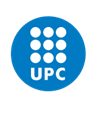

**ADVANCED AEROELASTICITY**

# **Section properties**

Virtual environment to get the stiffness and mass properties of a beam's cross-section.

clear

## 1. Cross-section specifications

### 1.1. Geometry

You can define any of the predefined cross-sections providing the parameters as an array in which each component corresponds to the corresponding $p_i$ value in the Appendix.

Example: For a rectangular cross-section of 10 mm width ($p_1$) and 15 mm height ($p_2$), choose 'rectangle' and define [10e-3,15e-3].

miltom = 1.0*25.4e-5;
c = 0.527;
h = 0.14*c;
t = 40*miltom; %20
t1 = 200*miltom;
t2 = 200*miltom;
p1 = 0.15*c;
p2 = 0.41*c;
geometry = "spars";
param = [c,h,t,p1,t1,p2,t2];
resolution = 1;

Alternatively, you can directly import the nodal coordinates and element connectivities matrices from files (only linear triangular or bilinear quadrilateral meshes are supported):

nodesFile = "";
elemsFile = "";

### 1.2. Material

density = 1551;
youngModulus = 70000000000;
poissonRatio = 0.3;

## 2. Mesh

Click to generate and visualize the mesh corresponding to the previous section specified data.

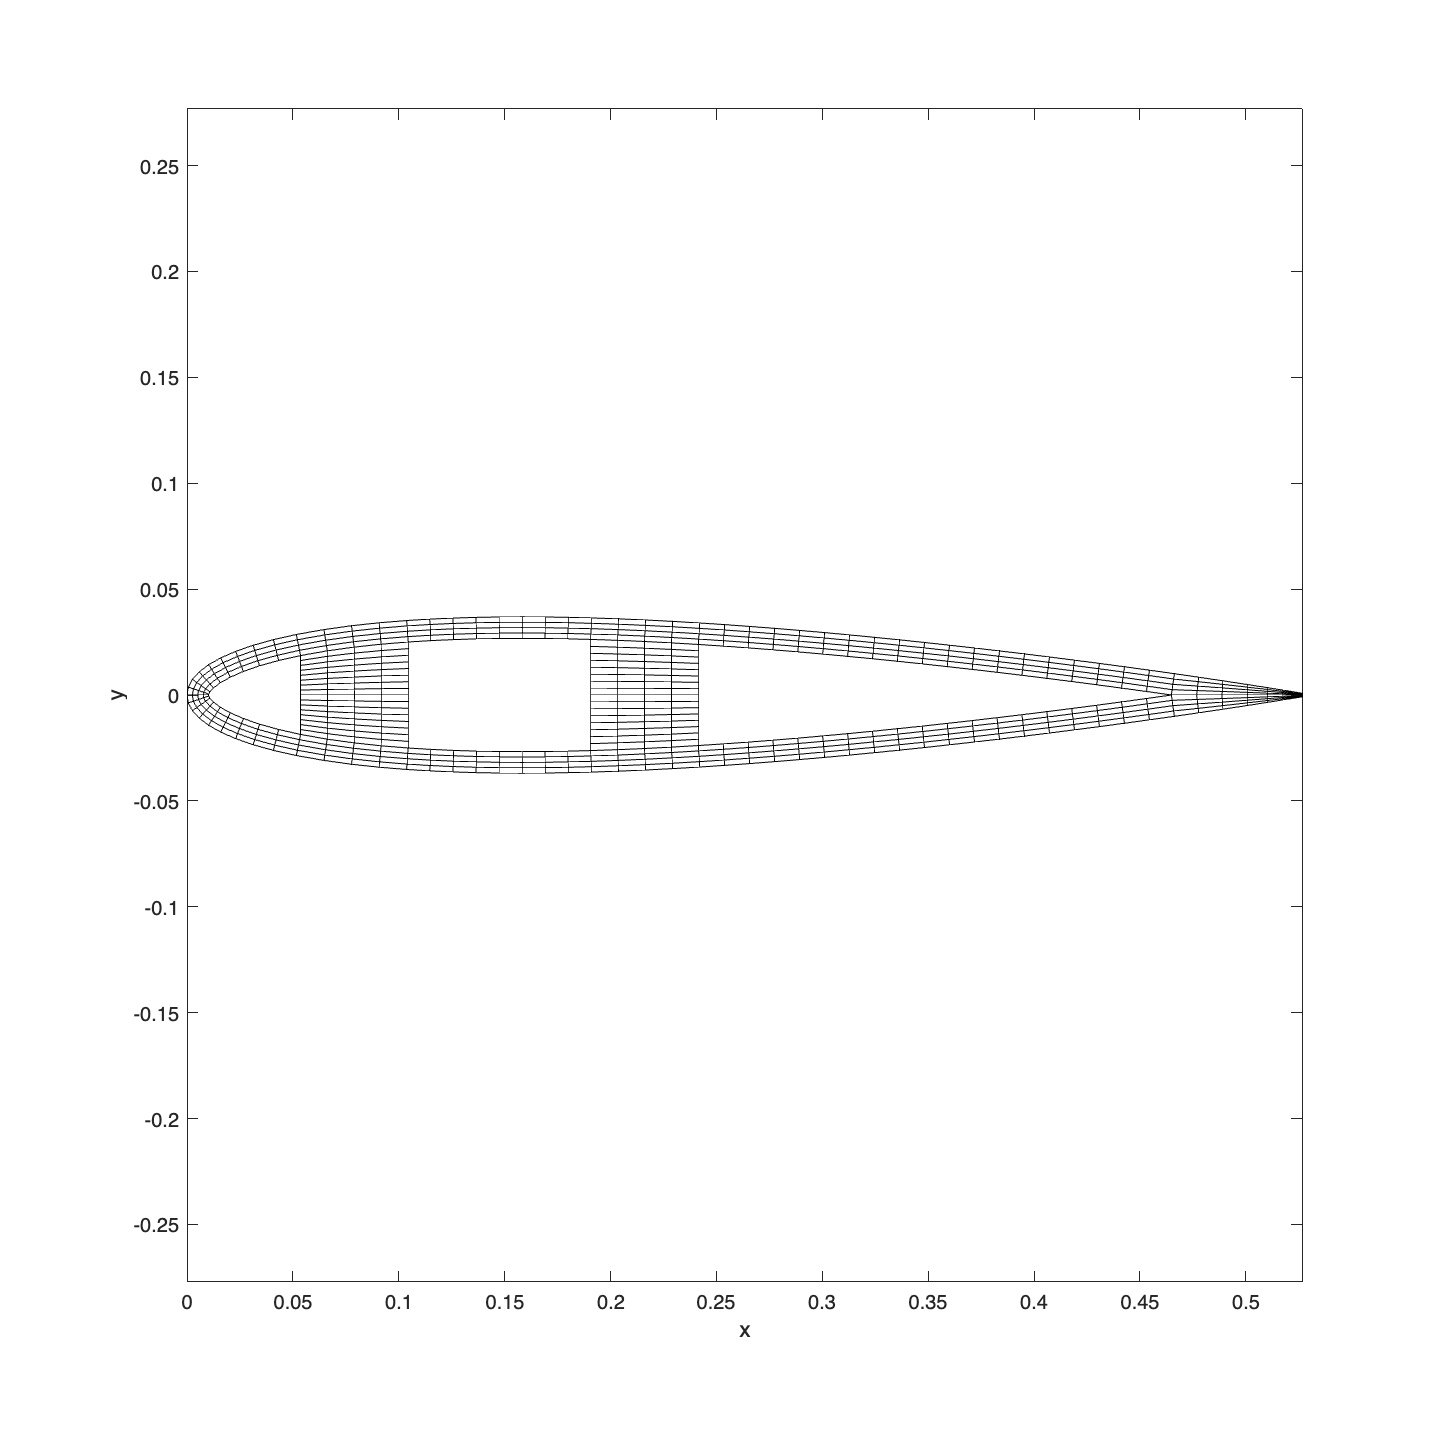

 

% Obtain mesh data
[nodes,mat,elems,elemat] = getMeshData(geometry,param,resolution,density,youngModulus,poissonRatio,nodesFile,elemsFile,true);

## 3. Compute section properties

Click to compute the cross-section properties:

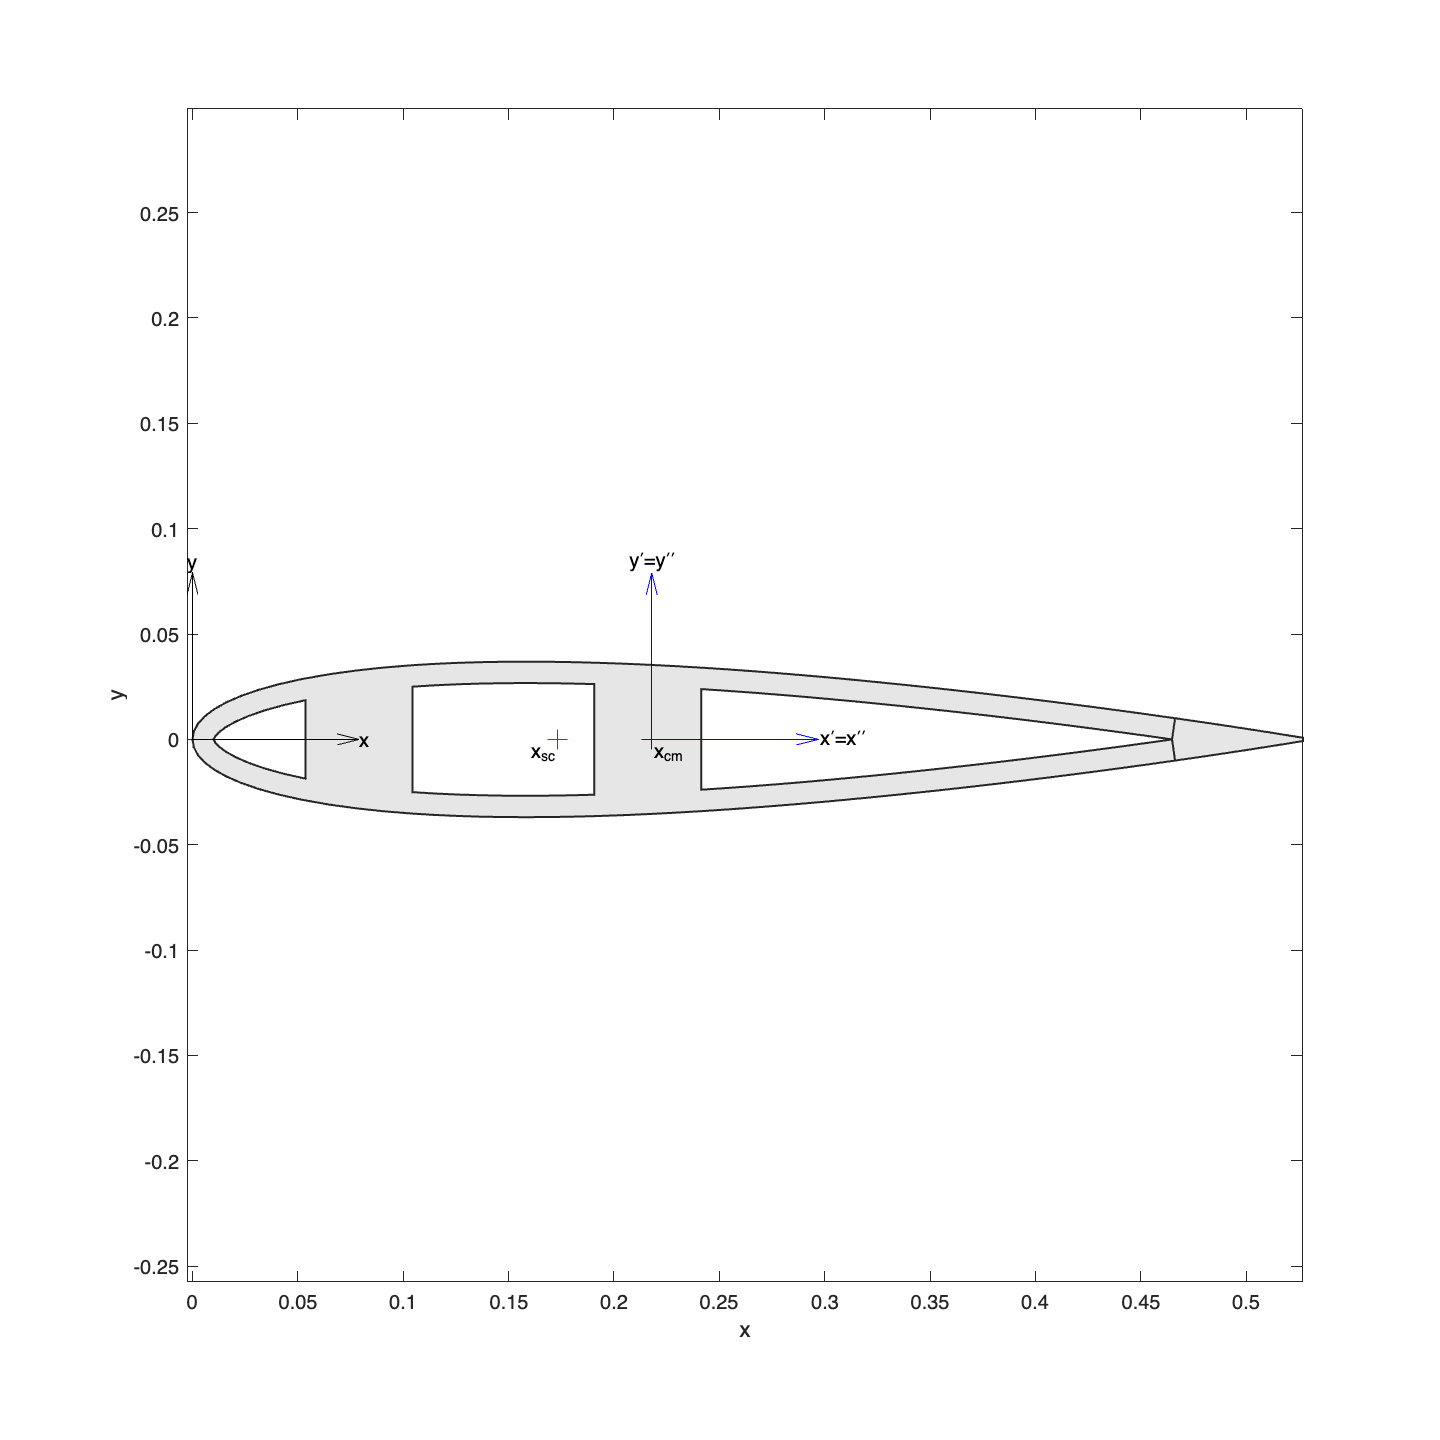

 

% Compute section properties 
section = getSectionProperties(nodes,mat,elems,elemat,true);

Geometrical properties referred to the reference ($x,y$) axes as defined in the Appendix (if a custom mesh is given, the reference axes correspond to the system in which the nodal coordinates data is provided):

- Section area: $A = \int_A\text{d}S$

fprintf("A = %.4g",section.A);

A = 0.01506

- Centroid (also center of mass): $\mathbf{x}_\text{cm} = \frac{1}{A}\int_A \mathbf{x} \text{d}S$

fprintf("x_cm = [ %.4g, %.4g]",section.xcm);

x_cm = [ 0.2179, 0]

- Shear center: $\mathbf{x}_\text{sc}$

fprintf("x_sc = [ %.4g, %.4g]",section.xsc);

x_sc = [ 0.1732, 0]

- Second moments of area with respect to reference axes: $I_{xx} = \int_A y^2\text{d}S, I_{yy}  = \int_A x^2\text{d}S, I_{xy} = \int_A xy\text{d}S$

fprintf("I_xx = %.4g",section.Ixx);

I_xx = 6.574e-06

fprintf("I_yy = %.4g",section.Iyy);

I_yy = 0.0009853

fprintf("I_xy = %.4g",section.Ixy);

I_xy = 0

- Second moments of area with respect to axes passing through the section's centroid: $I_{x\prime x\prime} = \int_A (y-y_\text{cm})^2\text{d}S, I_{y\prime y\prime} = \int_A (x-x_\text{cm})^2\text{d}S, I_{x\prime y\prime} = \int_A (x-x_\text{cm})(y-y_\text{cm})\text{d}S$ (if $\mathbf{x}_\text{cm} = (0, 0)$ then $I_{xx} = I_{x\prime x\prime}, I_{yy} = I_{y\prime y\prime}, I_{xy} = I_{x\prime y\prime}$) 

fprintf("I_x'x' = %.4g",section.Ixx_0);

I_x'x' = 6.574e-06

fprintf("I_y'y' = %.4g",section.Iyy_0);

I_y'y' = 0.0002698

fprintf("I_x'y' = %.4g",section.Ixy_0);

I_x'y' = 0

- Second moments of area with respect to principal axesof inertia and principal axes orientation with respect to reference axes: $I_{x\prime\prime}, I_{y\prime\prime}, \alpha$ (if $\alpha=0$ then $I_{x\prime x\prime} = I_{x\prime\prime}, I_{y\prime y\prime} = I_{y\prime\prime}, I_{x\prime y\prime} = 0$)

fprintf("I_x'' = %.4g",section.Ix);

I_x'' = 6.574e-06

fprintf("I_y'' = %.4g",section.Iy);

I_y'' = 0.0002698

fprintf("alpha = %.4g rad",section.alpha);

alpha = 0 rad

- Polar moment of area with respect to shear center: $I_\text{sc} = \int_A [(x-x_\text{sc})^2 + (y-y_\text{sc})^2]\text{d}S$ (not to be confused with its **mass inertia** equivalent, which would be $I_\text{sc}^\text{(m)} = \rho I_\text{sc}$ [kg·m])

fprintf("I_sc = %.4g",section.Isc);

I_sc = 0.0003066

- Shear factors: $k_x, k_y$ (it corrects the section area to account for the non-uniform shear stress distribution)

fprintf("k_x = %.4g",section.kx);

k_x = 0.628

fprintf("k_y = %.4g",section.ky);

k_y = 0.1709

- Torsion factor: $k_\text{t}$ (it corrects the polar moment of area to account for warping caused by the beam's twist, i.e., $J = k_\text{t}I_\text{sc}$)

fprintf("k_t = %.4g",section.kt);

k_t = 0.07241

The warping displacement:

scale =0.8;

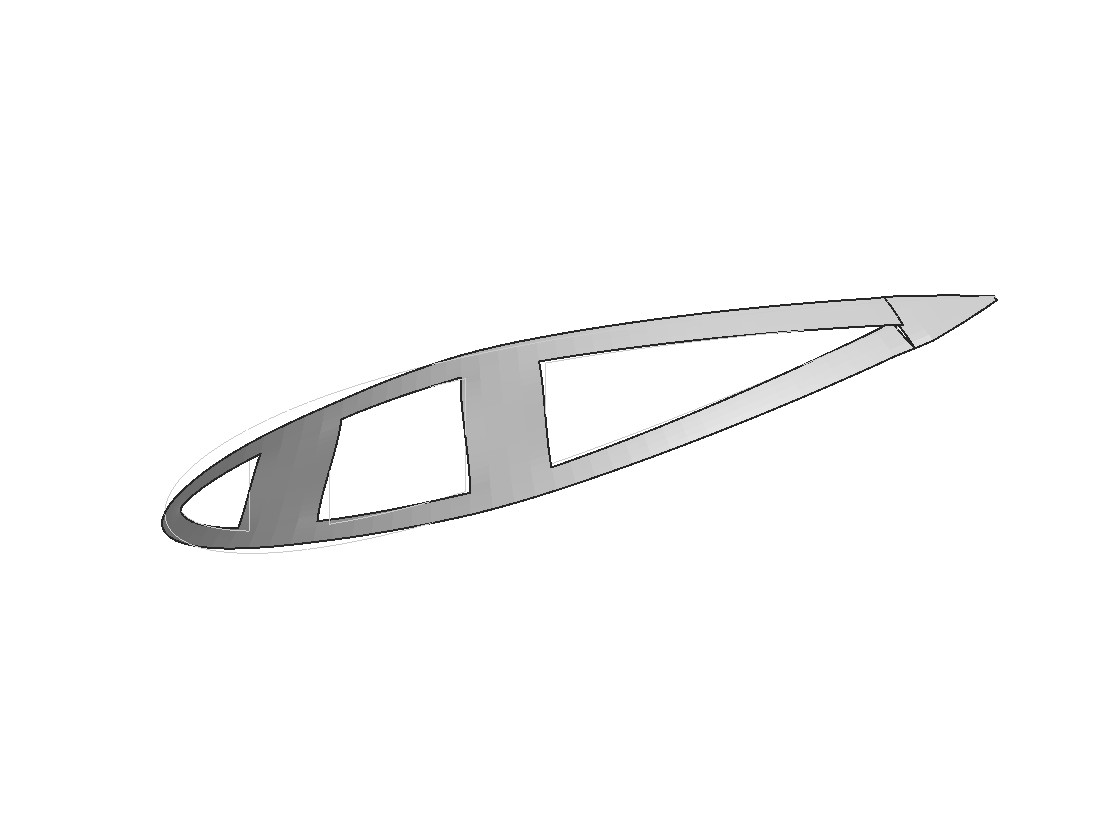

figure;
hold on; box on; axis equal; axis tight; view(45,15); light;
for i = 1:length(section.bnd_elems)
    patch(zeros(size(section.bnd_elems{i}')),reshape(nodes(section.bnd_elems{i}',1),size(section.bnd_elems{i}')),reshape(nodes(section.bnd_elems{i}',2),size(section.bnd_elems{i}')),ones(size(section.bnd_elems{i}')),'FaceColor','none','Edgecolor',0.8*[1,1,1],'LineStyle','--');
    patch(reshape(scale*section.warp(section.bnd_elems{i}'),size(section.bnd_elems{i}')),reshape(nodes(section.bnd_elems{i}',1),size(section.bnd_elems{i}')),reshape(nodes(section.bnd_elems{i}',2),size(section.bnd_elems{i}')),reshape(section.warp(section.bnd_elems{i}'),size(section.bnd_elems{i}')),'FaceColor','none','Edgecolor',0.15*[1,1,1],'LineWidth',1);
end
patch(reshape(scale*section.warp(elems'),size(elems')),reshape(nodes(elems',1),size(elems')),reshape(nodes(elems',2),size(elems')),reshape(section.warp(elems'),size(elems')),'FaceColor',0.9*[1,1,1],'Edgecolor','none');
set(gca,'xcolor','none','ycolor','none','zcolor','none');

Note: Using the parallel axis theorem, the second moments of area with respect to any axis parallel to the reference axes passing through the section's centroid can be obtained:

    
$$I_{\hat{x}\hat{x}} = I_{x\prime x\prime} + (\hat{y} - y_\text{cm})^2A$$


    
$$I_{\hat{y}\hat{y}} = I_{y\prime y\prime} + (\hat{x} - x_\text{cm})^2A$$
 

    
$$I_{\hat{x}\hat{y}} = I_{x\prime y\prime} + (\hat{x} - x_\text{cm})(\hat{y} - y_\text{cm})A$$


## Appendix. Predefined cross-sections catalog

### Rectangle

`'rectangle'`

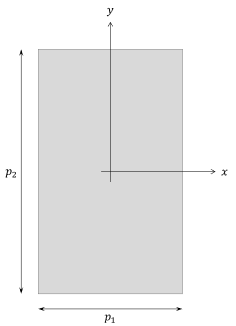

### **Rectangle frame**

`'frame'`

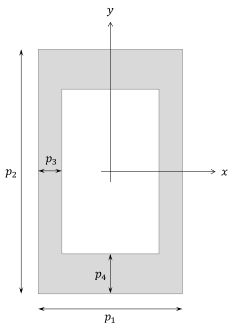

### Circle

`'circle'`

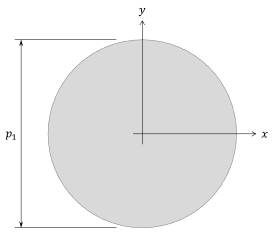

### **Ring**

`'ring'`

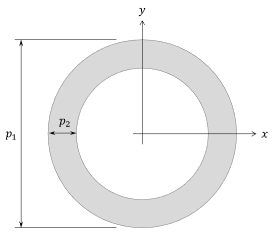

### L-shaped

`'l'`

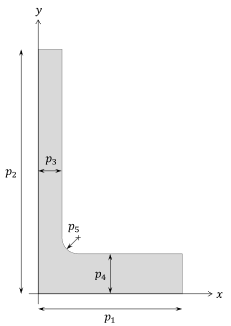

### T-shaped

`'t'`

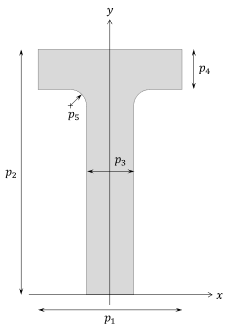

### `I`-shaped

`'i'`

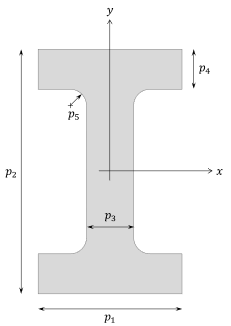

### C-shaped

`'c'`

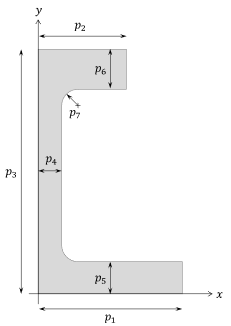

### Z-shaped

`'z'`

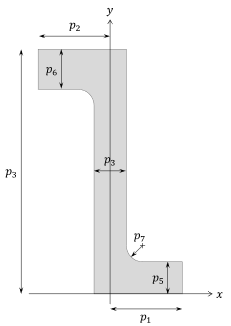

### **NACA00 airfoil**

`'naca'`


$$y(x) = \pm p_2 \left[ 0.2969 \sqrt{\frac{x}{p_1}} - 0.1260 \left( \frac{x}{p_1} \right) - 0.3516 \left( \frac{x}{p_1} \right)^2 + 0.2843 \left( \frac{x}{p_1} \right)^3 - 0.1015\left( \frac{x}{p_1} \right)^4 \right]$$


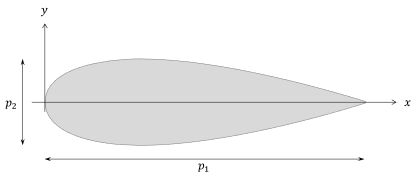

### **NACA00 airfoil (rib with holes)**

`'rib' `(the number of holes is determined by the number of input parameters)

### 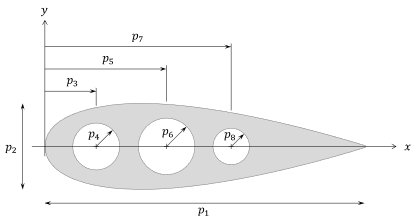

### **NACA00 airfoil (skin)**

`'skin'`

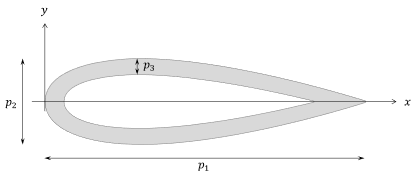

### **NACA00 airfoil (reinforced leading and trailing edges)**

`'edges'`

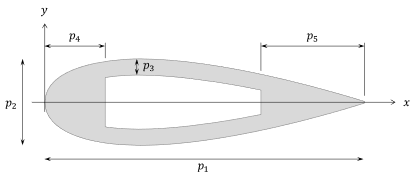

### **NACA00 airfoil (spars)**

`'spars' `(the number of spars is determined by the number of input parameters)

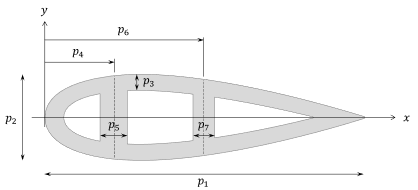

### **NACA00 airfoil (wingbox)**

`'wingbox'`